%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 151433*0.946

W = 1.4326e+05


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1561; %ft^2
AR = 8.75

AR = 8.7500

AR2 = 5.23

AR2 = 5.2300

b2=100

b2 = 100

TaperRatio = 0.6;
b = sqrt(AR*S)

b = 116.8707

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.9;
% K = 1/(e*pi*AR)

%Fuselage Parameters
Df = 15.17; %ft
LNose = 13.33; %ft
LMid = 44; %ft
LTail = 37.3 %ft

LTail = 37.3000

DBase = 1.5 %ft

DBase = 1.5000

ABase = pi*DBase^2/4

ABase = 1.7671

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.8290

Sexp = 1.3143e+03

Re = 7.5922e+07

SweepMaxT = -0.9821

FF = 1.7037

Swet = 2.7009e+03

CDo = 0.0065


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0021


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0015


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.2628

CDoFuse = 0.0057


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

CDoNacelle = 0.0011


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0062


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0031


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 1.1502e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0262


%Induced Drag Factor

Ne = 4; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)

TaperFunc = 0.0050

K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)

K = 0.0498

e = 1/(K*AR*pi)

e = 0.7310


CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

CD =     0.0387    0.0415    0.0412    0.0408    0.0405    0.0402    0.0399    0.0396    0.0393    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0412    0.0408    0.0405    0.0402    0.0399    0.0396    0.0393    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0408    0.0405    0.0402    0.0399    0.0396    0.0393    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0405    0.0402    0.0399    0.0396    0.0393    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0402    0.0399    0.0396    0.0393    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0399    0.0396    0.0393    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0396    0.0393    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0393    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0390    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0388    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0385    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0382    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0380    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0377    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0375    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0372    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0370    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0368    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0366    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0364    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0362    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0360    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0358    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0356    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0354    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0352    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0351    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0349    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0348    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0346    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0345    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0344    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0343    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0342    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0340    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0340    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0339    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0338    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0337    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0336    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0336    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0266    0.0335    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0266    0.0265    0.0334    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0266    0.0265    0.0265    0.0334    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0266    0.0265    0.0265    0.0264    0.0334    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0266    0.0265    0.0265    0.0264    0.0264    0.0333    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0266    0.0265    0.0265    0.0264    0.0264    0.0263    0.0333    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0266    0.0265    0.0265    0.0264    0.0264    0.0263    0.0263    0.0333    0.0333


CD =     0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0274    0.0272    0.0271    0.0269    0.0268    0.0267    0.0266    0.0265    0.0265    0.0264    0.0264    0.0263    0.0263    0.0263    0.0333


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 0.3812

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 0.7619

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 1.1417

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 1.5203

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 1.8972

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 2.2719

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 2.6441

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 3.0133

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 3.3792

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 3.7413

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 4.0995

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 4.4531

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 4.8021

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 5.1459

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 5.4844

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 5.8172

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 6.1441

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 6.4648

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 6.7791

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 7.0869

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 7.3878

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 7.6818

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 7.9686

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 8.2482

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 8.5205

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 8.7853

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 9.0426

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 9.2924

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 9.5345

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 9.7690

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 9.9958

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 10.2150

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 10.4265

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 10.6305

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 10.8269

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 11.0158

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 11.1974

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 11.3715

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 11.5385

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 11.6983

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 11.8510

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 11.9968

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 12.1358

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 12.2682

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 12.3939

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 12.5133

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 12.6263

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 12.7333

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 12.8342

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 12.9293

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.0186

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.1025

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.1809

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.2541

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.3222

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.3853

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.4436

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.4973

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.5464

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.5912

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.6318

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.6683

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.7009

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.7296

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.7547

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.7763

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.7945

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.8093

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.8211

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.8297

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.8355

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.8385

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


LDMax = 13.8387

CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


CD = 1×30
    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0354    0.0350    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0320    0.0317    0.0313    0.0310    0.0307    0.0304    0.0301    0.0299    0.0296    0.0293    0.0291    0.0289    0.0286    0.0284


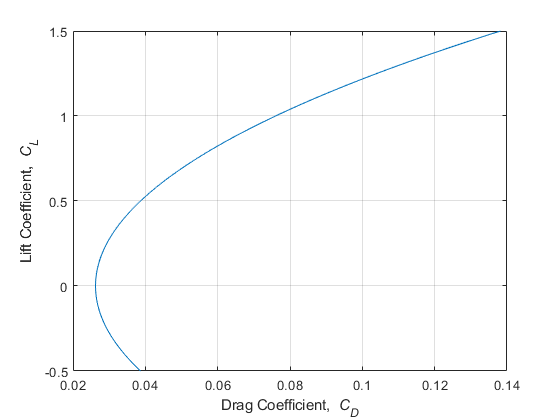


plot (CD,CL)
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on


LDMax

LDMax = 13.8387